% 로봇 불러오기
urdfPath = 'C:\Users\변재형\Documents\MATLAB\로봇시뮬링크파일\robot\nuri3s_urdf\nuri3s_matlab\nuri3s.urdf'

urdfPath = 'C:\Users\변재형\Documents\MATLAB\로봇시뮬링크파일\robot\nuri3s_urdf\nuri3s_matlab\nuri3s.urdf'

robot = importrobot(urdfPath);
robot.DataFormat = 'row';
robot.Gravity = [0 0 -9.81];

% 초기 포즈
config = homeConfiguration(robot);

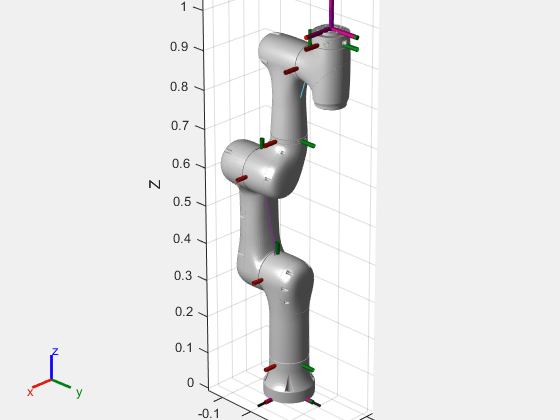

% 애니메이션을 위한 figure 생성
figure;
ax = show(robot, config);
view(135, 25);
axis equal;
hold on;

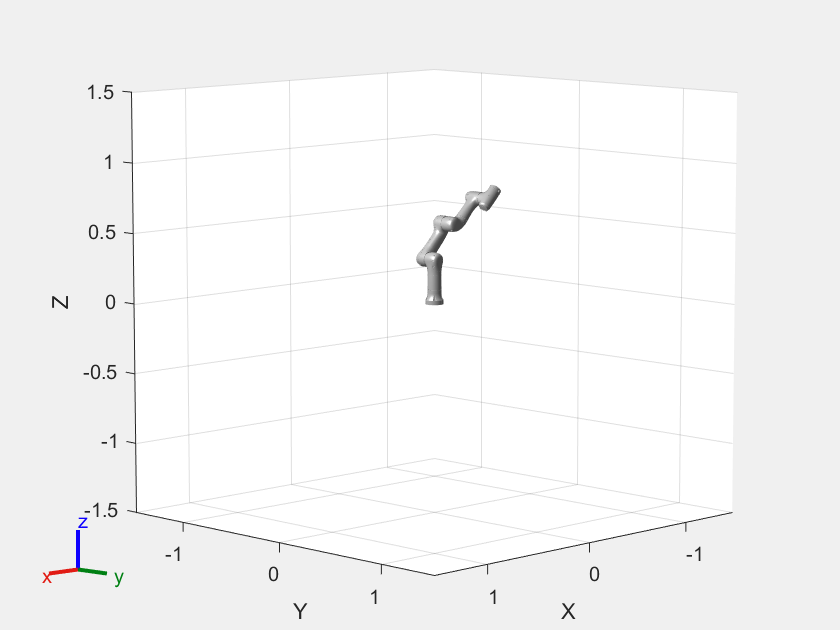

Error using newplot (line 48)
Argument must be a scalar handle to an existing graphics object.
Error in robotics.manip.internal.RigidBodyTree/simpleShow (line 1317)
                ax = newplot(parent);
Error in 

% 움직일 조인트 (예: joint 1)
% 한 번만 생성
%figure('Name', 'Nuri3s Robot');
%ax = axes;

% 반복 실행
%for t = linspace(0, 1, 100)
    %config(1).JointPosition = pi/2 * sin(2*pi*t);
    %config(2).JointPosition = pi/4 * cos(2*pi*t);
    %config(3).JointPosition = pi/6 * sin(4*pi*t);
    
    %show(robot, config, 'PreservePlot', false, 'Frames', 'off', 'Parent', ax);
    %pause(0.02);
%end

% 로봇 불러오기 (URDF 경로는 사용자 환경에 맞게 조정)
robot = importrobot("nuri3s.urdf");  % 또는 본인이 쓰는 URDF 경로
robot.DataFormat = 'row';           % 필수!
robot.Gravity = [0 0 -9.81];

% q_start, q_goal: 1x6 row vector (각도는 라디안)
q_start = [0 0 0 0 0 0];  % 시작 자세
q_goal_deg = [50 0 -90 0 -90 0]
% q_goal_deg = [0.00062942505 24.991459 115.004166 0.0083909095 90.0107 -0.017990112];  % 도 단위 목표
q_goal = deg2rad(q_goal_deg);  % 라디안으로 변환

q_goal_deg =     50     0   -90     0   -90     0


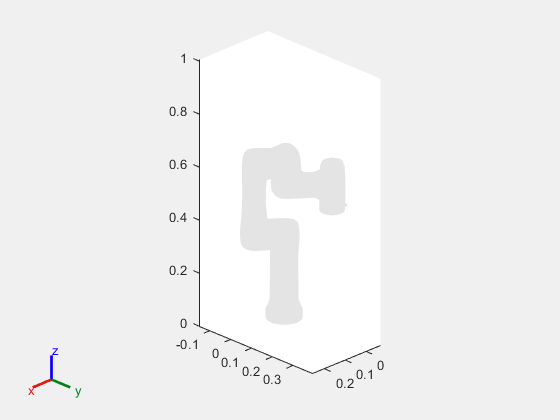


% Figure 설정
figure;
ax = axes;
view(ax, 135, 25);
axis equal;
hold on;

% 초기 상태 출력
show(robot, q_start, 'Frames', 'off', 'PreservePlot', false, 'Parent', ax);

% 애니메이션: 선형 보간
numSteps = 100;
for k = 1:numSteps
    alpha = k / numSteps;
    q_now = (1 - alpha) * q_start + alpha * q_goal;

    show(robot, q_now, 'Frames', 'off', 'PreservePlot', false, 'Parent', ax);
    pause(0.02);
end